clear
clc

syms s
z = simplify((2*s)/(2*s + 1))

$$z = \frac{2\,s}{2\,s+1}$$

% check for poles
[n,d] = numden(z);
poles = solve(d==0)

$$poles = -\frac{1}{2}$$

zeros = solve(n==0)

$$zeros = 0$$


% existence of poles or zeros
% Degree of numerator more or equal than denominator
if (polynomialDegree(n)==polynomialDegree(d))
   
    % if has a pole at 0
    
    synthesized = 1/limit(z*s,s,0) % capacitor series
    
    newFunction = simplify(z-1/(s*synthesized))
    
    
    % if has a pole at infinity
    
    synthesized = limit(z/s,s,inf) % inductor series
    
    newFunction = simplify(z-(s*synthesized))
    
    
    % if has a zero at 0
    y = 1/z;
    synthesized = 1/limit(y*s,s,0) %inductor shunt
    
    newFunction = simplify(y - 1/(s*synthesized))
    
    % if has a zero at infinity
    y = 1/z
    synthesized = limit(y/s,s,inf) % capacitor shunt
    
    newFunction = simplify(y-s*synthesized) 
end

$$synthesized = \infty$$

$$newFunction = \frac{2\,s}{2\,s+1}$$

$$synthesized = 0$$

$$newFunction = \frac{2\,s}{2\,s+1}$$

$$synthesized = 2$$

$$newFunction = 1$$

$$y = \frac{2\,s+1}{2\,s}$$

$$synthesized = 0$$

$$newFunction = \frac{2\,s+1}{2\,s}$$

if (polynomialDegree(n)>polynomialDegree(d))
    [r,q] = polynomialReduce(n,d)
    synthesized = q
    newFunction = r/d
end

% Degree of denominator more than numerator 
if (polynomialDegree(n)<polynomialDegree(d))
    [r,q] = polynomialReduce(d,n);
    synthesized = q % will be a capacitor
    newFunction = r/n
end


%if z has no poles and zeros
syms w s
f =@(s) (s^2 + 2*s + 4)/(2*s^2 + s + 2)

f = function_handle with value:
    @(s)(s^2+2*s+4)/(2*s^2+s+2)


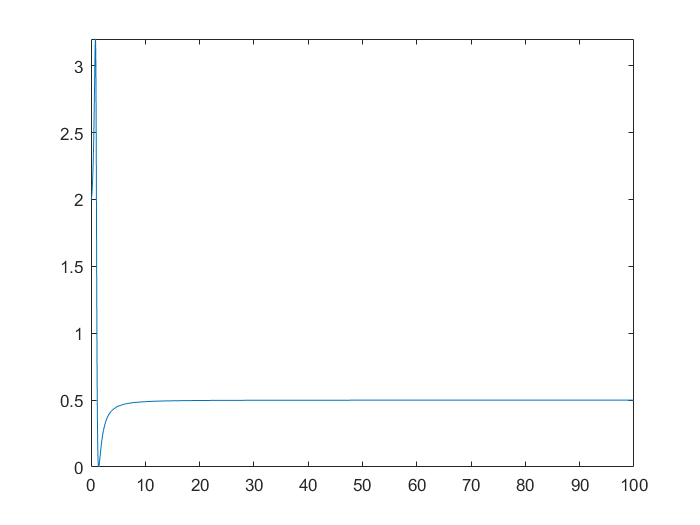

$$W = \left(\begin{array}{c} -\frac{\sqrt{\sqrt{33}-1}}{2}\\ \frac{\sqrt{\sqrt{33}-1}}{2} \end{array}\right)$$

%temp =f(s);
a = true;
if (a)
    re1 = real(f(j*w));
    fplot(re1,[0,100])
    % get omega get r 
    min = 1;
    [W] = solve(real(f(j*real(w)))==min,w)
end

newZ = simplify(f(s)-min)

$$newZ = \frac{-s^{2}+s+2}{2\,s^{2}+s+2}$$



t = factor(2*s*s+s+2)

$$t = 2\,s^{2}+s+2$$